cd('/Volumes/PcSSDA/RvR/20220329_1626_RvR_001')
ExperimentName='20220329_1626_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 
mouse = '1626';
recording = '001';

i = 1;
filename=[analysis_name,num2str(i),'_20220403.mat'];
load(filename)

speed_csv=['data/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-03-29 11:14:23.0932224'

reference_time=datetime(reference_time)

reference_time = datetime
   29-Mar-2022 11:14:23



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


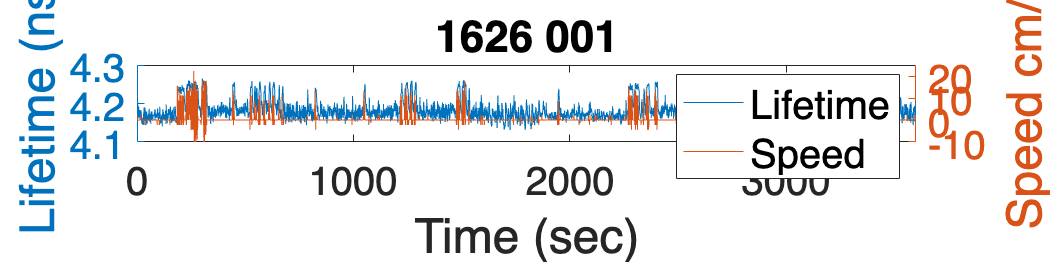

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
% ylim([4.15 4.25])
% yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Lifetime','Speed','FontSize',20)
title([mouse ' ' recording])

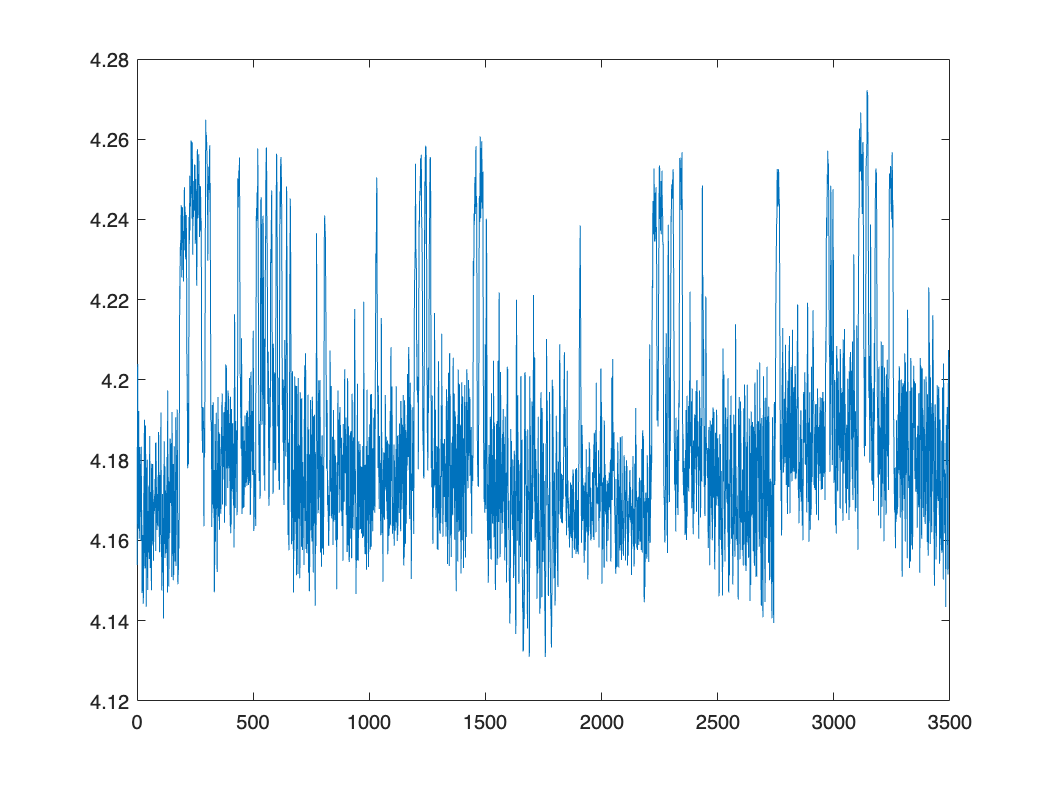

figure
plot(tau_empTrunc)

resting_index = 118;
running_index = 297;
resting_histogram = lifetime_histograms(:,resting_index);
running_histogram = lifetime_histograms(:,running_index);
resting_histogram_norm = resting_histogram/max(resting_histogram);
running_histogram_norm = running_histogram/max(running_histogram);

cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
ExperimentName='20220329_1626_SW_004'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 17; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 


load('FLP_analysis_0426.mat')

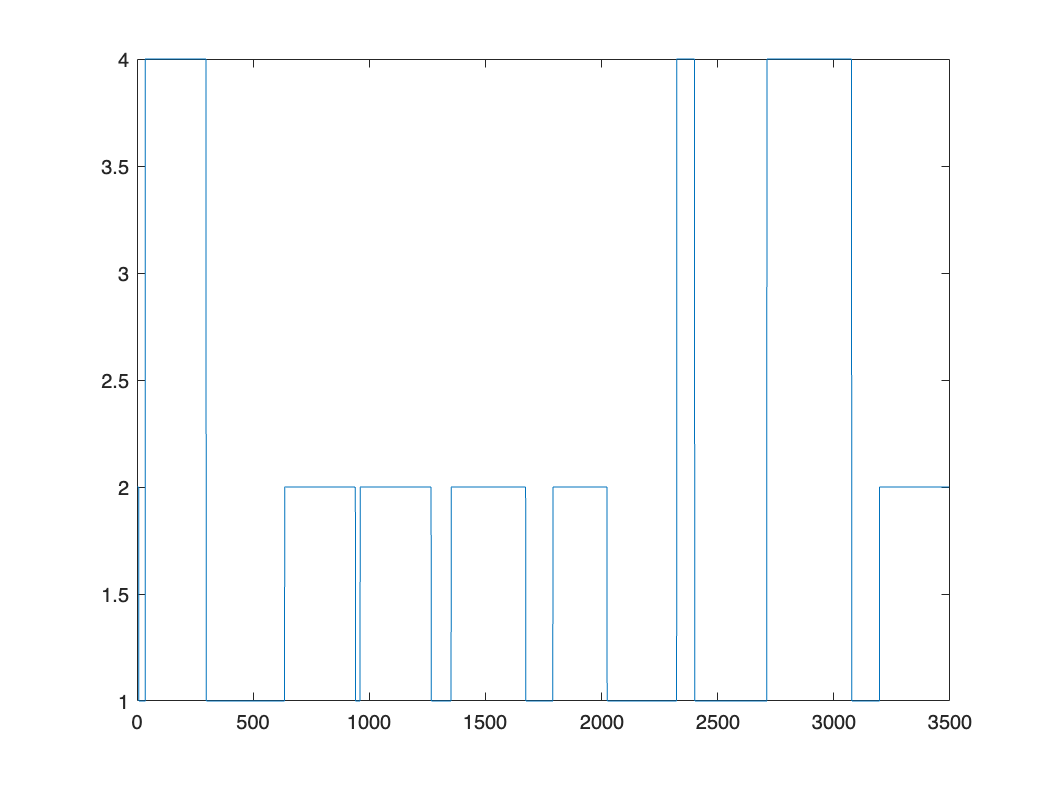

figure
plot(states_for_time_11)

i = 2;
filename=[analysis_name,num2str(i),'h_20220403.mat'];
load(filename)

NREM_index = 751;
AW_index = 382;
NREM_histogram = lifetime_histograms(:,NREM_index);
AW_histogram = lifetime_histograms(:,AW_index);
NREM_histogram_norm = NREM_histogram/max(NREM_histogram);
AW_histogram_norm = AW_histogram/max(AW_histogram);

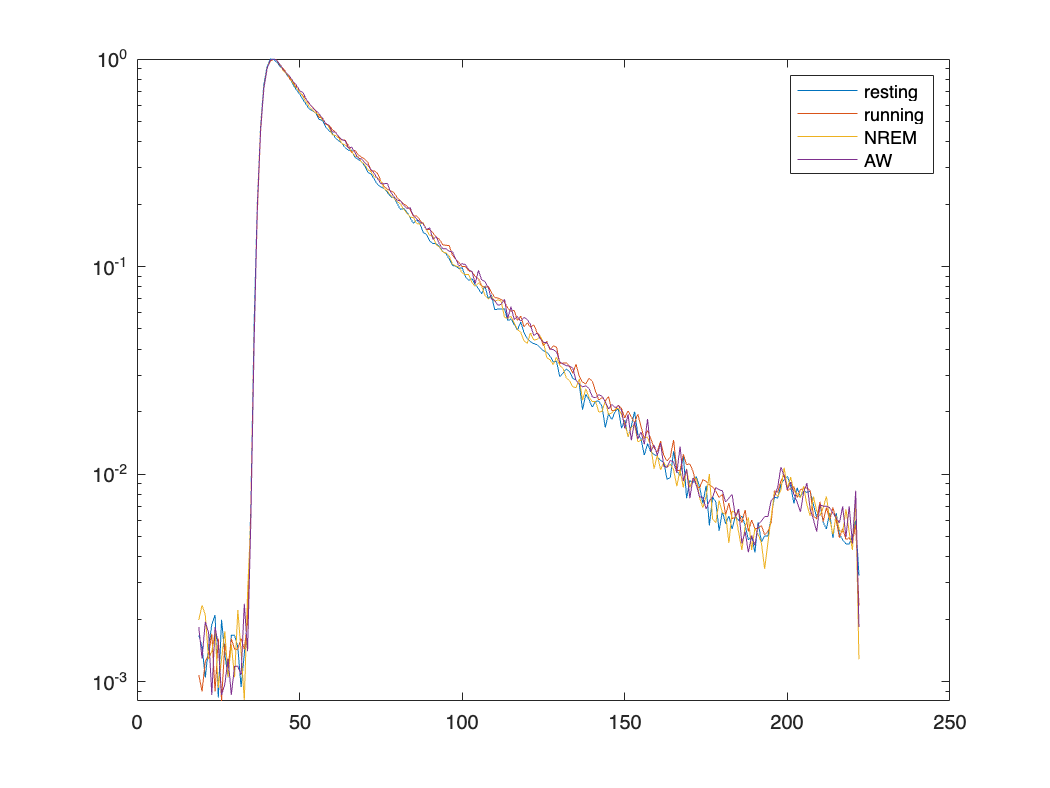

figure
semilogy(resting_histogram_norm)
hold on
semilogy(running_histogram_norm)
hold on
semilogy(NREM_histogram_norm)
hold on
semilogy(AW_histogram_norm)
legend('resting', 'running', 'NREM', 'AW')

figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


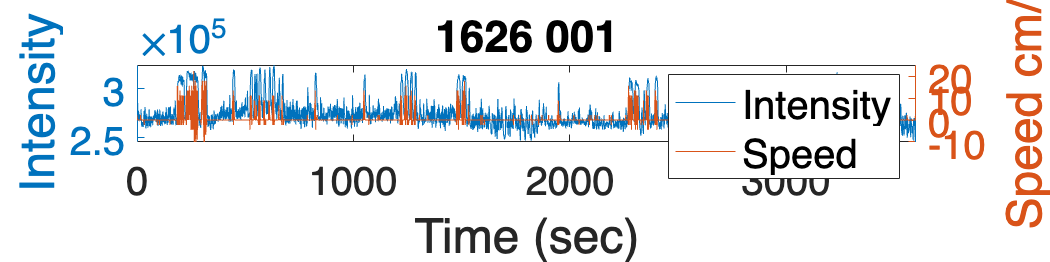

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
% ylim([350000 450000])
% yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Intensity','Speed','FontSize',20)
title([mouse ' ' recording])

cd('/Volumes/PcSSDA/RvR/20220325_1611_RvR_001')
ExperimentName='20220325_1611_RvR_001'; % Give a specific name to this experiment or this analysis
FirstAcq=7;
number_of_acq = 1;

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 
mouse = '1611';
recording = '001';

i = 1;
filename=[analysis_name,num2str(i),'_20220403.mat'];
load(filename)

speed_csv=['timestamp_speed/',ExperimentName,'_speed0.csv'];
[time_of_speed speed]=csvimport(speed_csv,'columns',[1,2],'noHeader',true);
time_of_speed(1)=[];
speed(1)=[];

speed=str2double(speed); 

time_of_speed_seconds=[];
time_of_speed_string=string;
reference_time=[time_of_speed{1}(1:10),' ',time_of_speed{1}(12:27)]

reference_time = '2022-03-25 13:00:56.8801408'

reference_time=datetime(reference_time)

reference_time = datetime
   25-Mar-2022 13:00:56



for i=1:size(time_of_speed,1)
    hour_num=str2num(time_of_speed{i}(12:13));
    min_num=str2num(time_of_speed{i}(15:16));
    sec_num=str2num(time_of_speed{i}(18:27));
    time_of_speed_seconds(i)=3600*hour_num+60*min_num+sec_num;
%     a=[time_of_speed{i}(1:10),' ',time_of_speed{i}(12:27)];
%     time_of_speed_string(i)=a;
%     time_of_speed_seconds(i)=second(datetime(a)-reference_time);
end


time_of_speed_seconds=time_of_speed_seconds-time_of_speed_seconds(1);

figure1=figure;
figure1.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


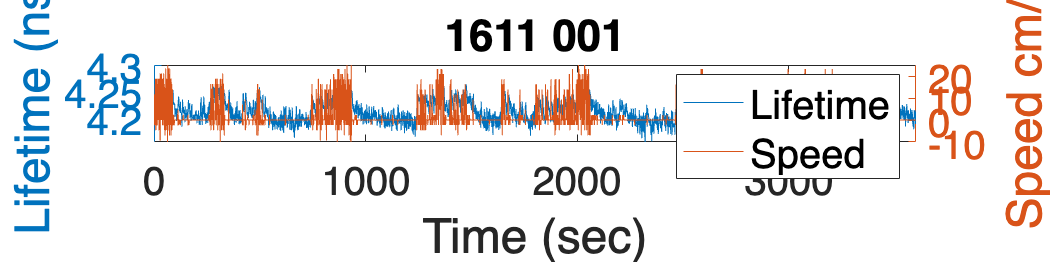

yyaxis left
plot(time,tau_empTrunc);
ylabel('Lifetime (ns)','FontSize',24)
% ylim([4.15 4.25])
% yticks([4.15 4.20 4.25 4.3])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Lifetime','Speed','FontSize',20)
title([mouse ' ' recording])

figure2=figure;
figure2.Position=[10 10 1200 300];
ax=gca;
ax.FontSize=20

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


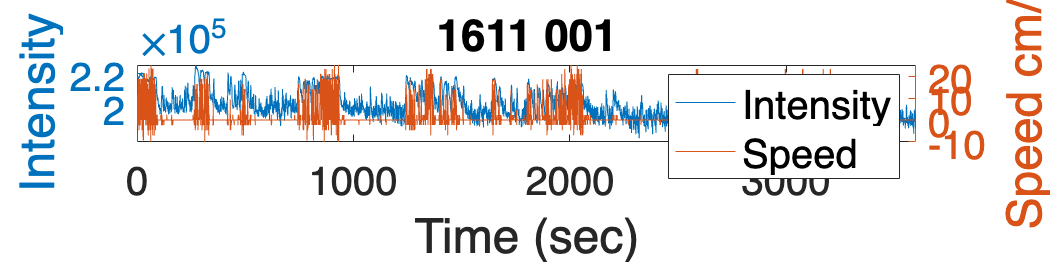

yyaxis left
plot(time,photoncount);
ylabel('Intensity','FontSize',24)
% ylim([350000 450000])
% yticks([550000 600000 650000])
yyaxis right
plot(time_of_speed_seconds,speed)
ylabel('Speed cm/s','FontSize',24)
ylim([-10 25])
yticks([-10 0 10 20])
xlim([0 3600])
% xticks([0 100 200 300])
xlabel('Time (sec)','FontSize',24)
legend('Intensity','Speed','FontSize',20)
title([mouse ' ' recording])